# TP #09 - Ejercicio 08

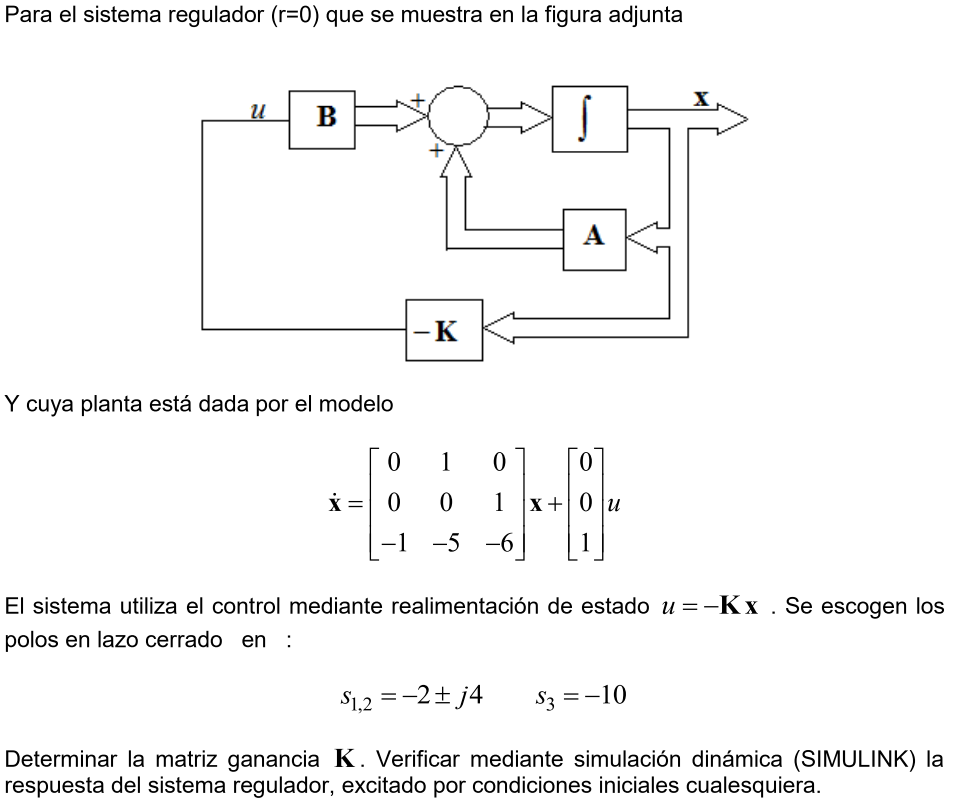

Del enunciado


$$\begin{array}{l}
\mathrm{PLC}:\;\left(s+2+\mathrm{j4}\right)\;\left(s+2+\mathrm{j4}\right)\;\left(s+10\right)\;\\
\mathrm{PLC}:\;\left(s^2 +4s+20\right)\left(s+10\right)\\
{\mathrm{PLC}:\;s}^3 +s^2 \;14+s\;60+200;\left(\mathbf{a}\right)
\end{array}$$


Con estos datos busquemos entonces la matríz 'K'


$$\begin{array}{l}
\overset{\ldotp }{X} \left(t\right)=\textrm{AX}\left(t\right)+B\mu \left(t\right);\mu \left(t\right)=-\textrm{KX}\left(t\right)\\
\overset{\ldotp }{X} \left(t\right)=\textrm{AX}\left(t\right)+B\left(-\textrm{KX}\left(t\right)\right)\\
\overset{\ldotp }{X} \left(t\right)=\left(A-\textrm{BK}\right)X\left(t\right)
\end{array}$$


Quedando entonces,


$$\begin{array}{l}
A-\textrm{BK}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-1 & -5 & -6
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
0\\
0\\
1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
k_1  & k_2  & k_3 
\end{array}\right\rbrack \\
A-\textrm{BK}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-1 & -5 & -6
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
0 & 0 & 0\\
0 & 0 & 0\\
k_1  & k_2  & k_3 
\end{array}\right\rbrack \\
A-\textrm{BK}=\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-1-k_1  & -5-k_2  & -6{-k}_3 
\end{array}\right\rbrack 
\end{array}$$


Finalmente hallamos la expresión de los polos deseados,


$$\begin{array}{l}
\left(\textrm{sI}-A+\textrm{BK}\right)=\left\lbrack \begin{array}{ccc}
s & 0 & 0\\
0 & s & 0\\
0 & 0 & s
\end{array}\right\rbrack -\left\lbrack \begin{array}{ccc}
0 & 1 & 0\\
0 & 0 & 1\\
-1-k_1  & -5-k_2  & -6{-k}_3 
\end{array}\right\rbrack \\
\left(\textrm{sI}-A+\textrm{BK}\right)=\left\lbrack \begin{array}{ccc}
s & -1 & 0\\
0 & s & -1\\
1+k_1  & 5+k_2  & s+6+k_3 
\end{array}\right\rbrack 
\end{array}$$


Hallamos ahora el determinante,


$$\textrm{det}\left(\textrm{sI}-A+\textrm{BK}\right)=s^3 +s^2 \;\left(6+k_3 \right)+s\;\left(5+k_2 \right)+k_1 +1$$


Reemplazando con lo hallado en **(a)**

- 
$$k_1 =199$$


- 
$$k_2 =55$$


- 
$$k_3 =8$$


Podemos además corroborar con la función 'acker'

A = [0 1 0; 0 0 1; -1 -5 -6];
B = [0; 0; 1];
C = eye(3);
PLC=[-2+4i -2-4i -10];
disp('Ganancias calculadas con Ackerman:')

Ganancias calculadas con Ackerman:


K=acker(A,B,PLC)

K =    199    55     8


disp('Vector de Realimentción de Estados ([An]):')

Vector de Realimentción de Estados ([An]):


An=A-B*K

An =      0     1     0
     0     0     1
  -200   -60   -14


disp('Posición diseñada de los polos a lazo cerrado:')

Posición diseñada de los polos a lazo cerrado:


PLC_d=eig(An)

PLC_d =   -2.0000 + 4.0000i
  -2.0000 - 4.0000i
 -10.0000 + 0.0000i


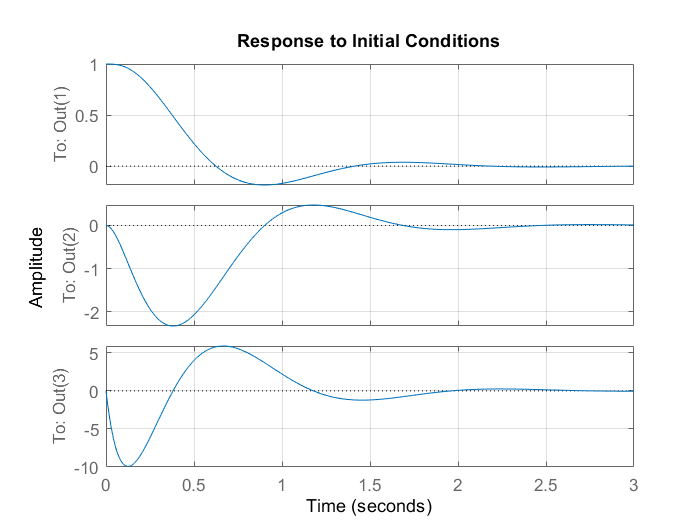

X0=[1; 0; 0];
sys=ss(An,[],C,[]);
initial(sys, X0);
grid on;

El mismo comportamiento lo podemos observar en Simulink, ejecutar ***TP09_ej08.slx.***

Notar que las condiciones iniciales están cargadas en los integradores.